## Testing bootstrap method for computing IRF estimator S.E.s

clear all
close all
%clc
warning off;

cd /Users/rogerchen/Documents/MATLAB/rc_thesis_irf/Emp_App/Ramey_Zubairy_replication_codes/

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% INPUT SPECIFICATION CHOICES 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

timesample=1; % 1 means 1889-2015; 2 means post WWII
statechoice=1;  % 1 means default unemp threshold; 2 means default ZLB threshold
shockchoice=1; % 1 means news shock; 2 means BP shock
transformation=1; % 1 means Gordon-Krenn; 2 means Hall-Barro-Redlick
taxchoice=0; %0 means no taxes as control; 1 means ad taxy as a control

trend=0; %4 means quartic; 2 means quadratic; 0 means no trend  
nlag=4;% number of lags of control variables
opt=0; % 0 means Newey-West with bandwidth=i; 1 means optimal bandwidth (takes much longer to run)'

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if transformation==1
    disp('Gordon-Krenn')
elseif transformation==2
    disp('Hall-Barro-Redlick')
end

Gordon-Krenn


if shockchoice==1
    disp('News shock')
elseif shockchoice==2
    disp('BP shock')
end

News shock



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hor=20; % horizon for IRFs
clevel= 1.96; % confidence level % 1.96  1.64;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
run('figure_irfs_multipliers_setup.m')

ans = 0.3584

Estimating Linear Model

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%LINEAR
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if trend==4
    xreg = [constant, t', tsq', tcu', tqu', shock];
    x = [xreg,  xorig]; %complete RHS
    x_la = [xreg(2:end, :), xorig_lagaug(2:end,:)];
    rpos=6; % position of shock
elseif trend==2
    xreg = [constant, t', tsq', shock];
    x= [xreg, xorig];
    x_la = [xreg(2:end, :), xorig_lagaug(2:end,:)];
    rpos=4;
elseif trend==0
    xreg = [constant, shock];
    x=[xreg,  xorig];
    x_la = [xreg(2:end,:), xorig_lagaug(2:end,:)];
    rpos=2;
end

% Generate the standard LP IRFs
[liny, confidencey]=linlp_rc(data,x,hor,rpos,transformation,clevel,opt,0,nlag);

  Columns 1 through 12

   -0.0060   -0.0057    0.0068   -0.0203    0.0087   -0.0085    0.0091   -0.0094    0.0026   -0.0029   -0.0060   -0.0024

  Columns 13 through 24

    0.0046    0.0035   -0.0061   -0.0064   -0.0049   -0.0044   -0.0053   -0.0002   -0.0044   -0.0025    0.0023    0.0062

  Columns 25 through 36

   -0.0079    0.0017   -0.0077   -0.0037   -0.0062   -0.0029    0.0178   -0.0038   -0.0098    0.0030   -0.0105   -0.0100

  Columns 37 through 48

    0.0050   -0.0081    0.0077    0.0008   -0.0042   -0.0034   -0.0070   -0.0123    0.0060    0.0014   -0.0025    0.0042

  Columns 49 through 60

   -0.0104    0.0043   -0.0076   -0.0011   -0.0033    0.0017   -0.0008   -0.0025   -0.0064   -0.0008   -0.0045    0.0018

  Columns 61 through 72

   -0.0062   -0.0047   -0.0060    0.0045   -0.0006   -0.0025    0.0028    0.0036   -0.0041    0.0177   -0.0068   -0.0104

  Columns 73 through 84

   -0.0043   -0.0076   -0.0093   -0.0014   -0.0028    0.0007    0.0060    0.0015    0.0007   -

Plotting RZ Standard Figures

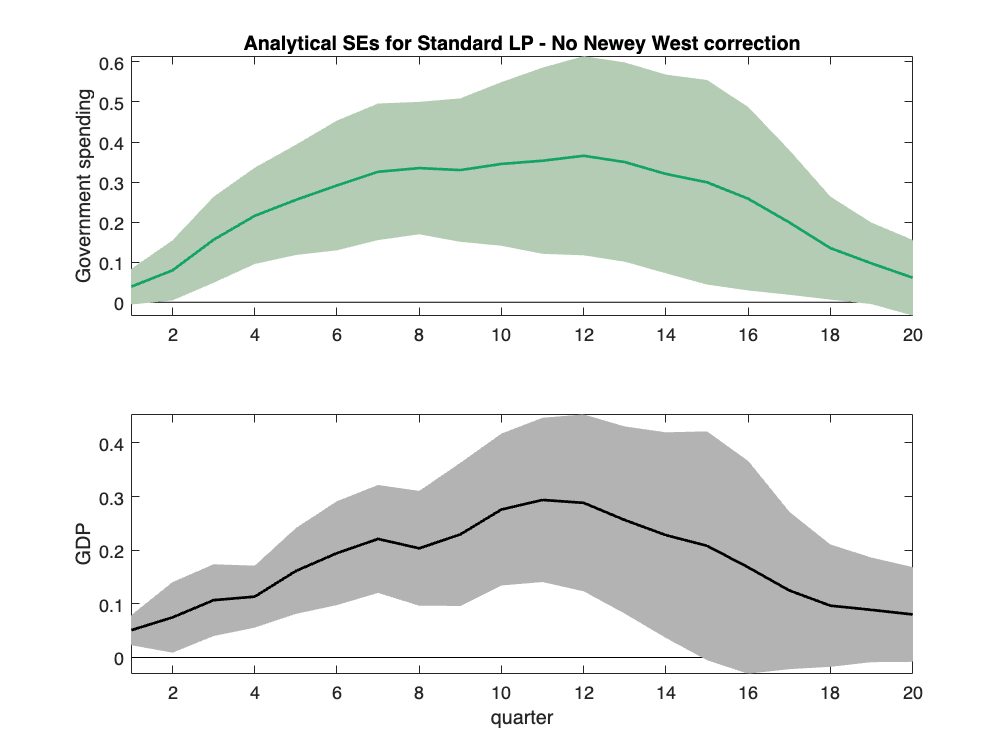

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Figures 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
zz=zeros(1,hor);
i=1;
figure(1)
subplot(2,1,1)
plot(1:1:hor, zz, 'k-')
hold on
% plot CIs
grpyat=[(1:1:hor)', confidencey(1,:,i)'; (hor:-1:1)' confidencey(2,hor:-1:1,i)'];
patch(grpyat(:,1), grpyat(:,2), [0.7 0.8 0.7],'edgecolor', [0.7 0.8 0.7]);
% plot point estimates
plot(1:1:hor, liny(i,:), 'Color', [0.08 0.64 0.4],'LineWidth', 1.5)
axis tight
ylabel('Government spending')
title('Analytical SEs for Standard LP - No Newey West correction')

i=2;
subplot(2,1,2)
plot(1:1:hor, zz, 'k-')
hold on
grpyat=[(1:1:hor)', confidencey(1,:,i)'; (hor:-1:1)' confidencey(2,hor:-1:1,i)'];
patch(grpyat(:,1), grpyat(:,2), [0.7 0.7 0.7],'edgecolor', [0.7 0.7 0.7]);
plot(1:1:hor, liny(i,:), 'Color', 'black','LineWidth', 1.5)

axis tight
ylabel('GDP')
xlabel('quarter')

Compute boostrap SEs for comparison (non-augmented)

% defining required variables
clear bs_confidencey
close all
[liny, bs_confidencey, bs_beta_means] = linlp_rc(data,x,hor,rpos,transformation, clevel, opt, 1, nlag);

entered loop of 2
  Columns 1 through 12

   -0.0060   -0.0057    0.0068   -0.0203    0.0087   -0.0085    0.0091   -0.0094    0.0026   -0.0029   -0.0060   -0.0024

  Columns 13 through 24

    0.0046    0.0035   -0.0061   -0.0064   -0.0049   -0.0044   -0.0053   -0.0002   -0.0044   -0.0025    0.0023    0.0062

  Columns 25 through 36

   -0.0079    0.0017   -0.0077   -0.0037   -0.0062   -0.0029    0.0178   -0.0038   -0.0098    0.0030   -0.0105   -0.0100

  Columns 37 through 48

    0.0050   -0.0081    0.0077    0.0008   -0.0042   -0.0034   -0.0070   -0.0123    0.0060    0.0014   -0.0025    0.0042

  Columns 49 through 60

   -0.0104    0.0043   -0.0076   -0.0011   -0.0033    0.0017   -0.0008   -0.0025   -0.0064   -0.0008   -0.0045    0.0018

  Columns 61 through 72

   -0.0062   -0.0047   -0.0060    0.0045   -0.0006   -0.0025    0.0028    0.0036   -0.0041    0.0177   -0.0068   -0.0104

  Columns 73 through 84

   -0.0043   -0.0076   -0.0093   -0.0014   -0.0028    0.0007    0.0060    0.

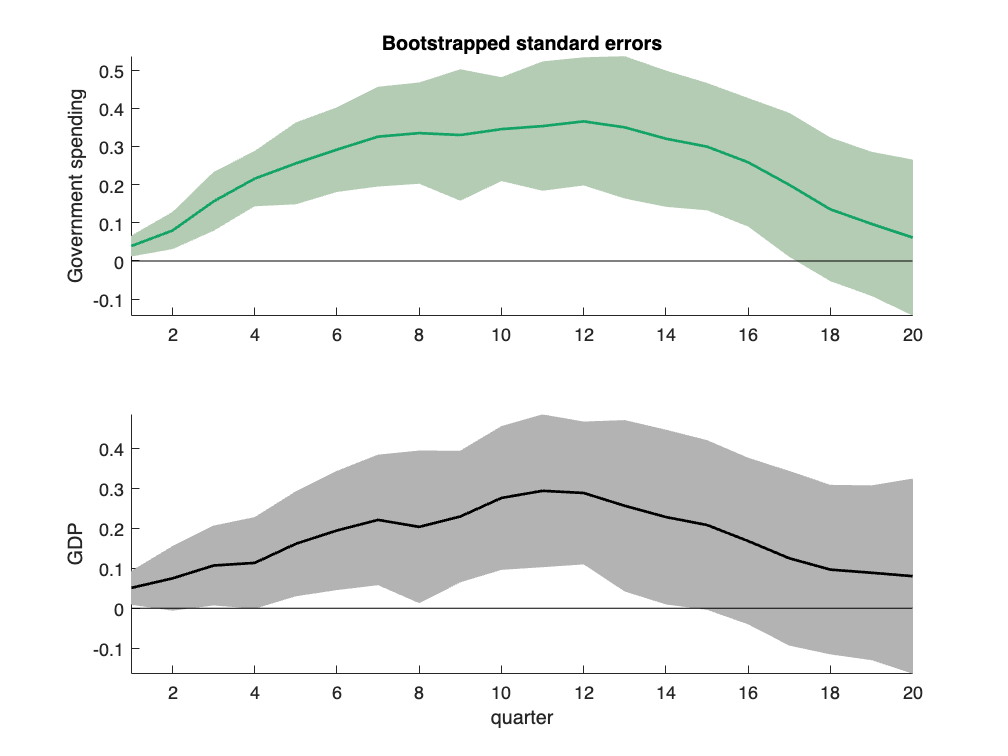

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Figures 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
zz=zeros(1,hor);
i=1;
figure(2)
subplot(2,1,1)
hold on
% plot CIs
grpyat=[(1:1:hor)', bs_confidencey(1,:,i)'; (hor:-1:1)' bs_confidencey(2,hor:-1:1,i)'];
patch(grpyat(:,1), grpyat(:,2), [0.7 0.8 0.7],'edgecolor', [0.7 0.8 0.7]);
% plot point estimates
plot(1:1:hor, liny(i,:), 'Color', [0.08 0.64 0.4],'LineWidth', 1.5)
plot(1:1:hor, zz, 'k-')
axis tight
ylabel('Government spending')
title('Bootstrapped standard errors')

i=2;
subplot(2,1,2)
hold on
grpyat=[(1:1:hor)', bs_confidencey(1,:,i)'; (hor:-1:1)' bs_confidencey(2,hor:-1:1,i)'];
patch(grpyat(:,1), grpyat(:,2), [0.7 0.7 0.7],'edgecolor', [0.7 0.7 0.7]);
plot(1:1:hor, liny(i,:), 'Color', 'black','LineWidth', 1.5)
plot(1:1:hor, zz, 'k-')
axis tight
ylabel('GDP')
xlabel('quarter')

Compare BS Betas to the Actual IRF Hor

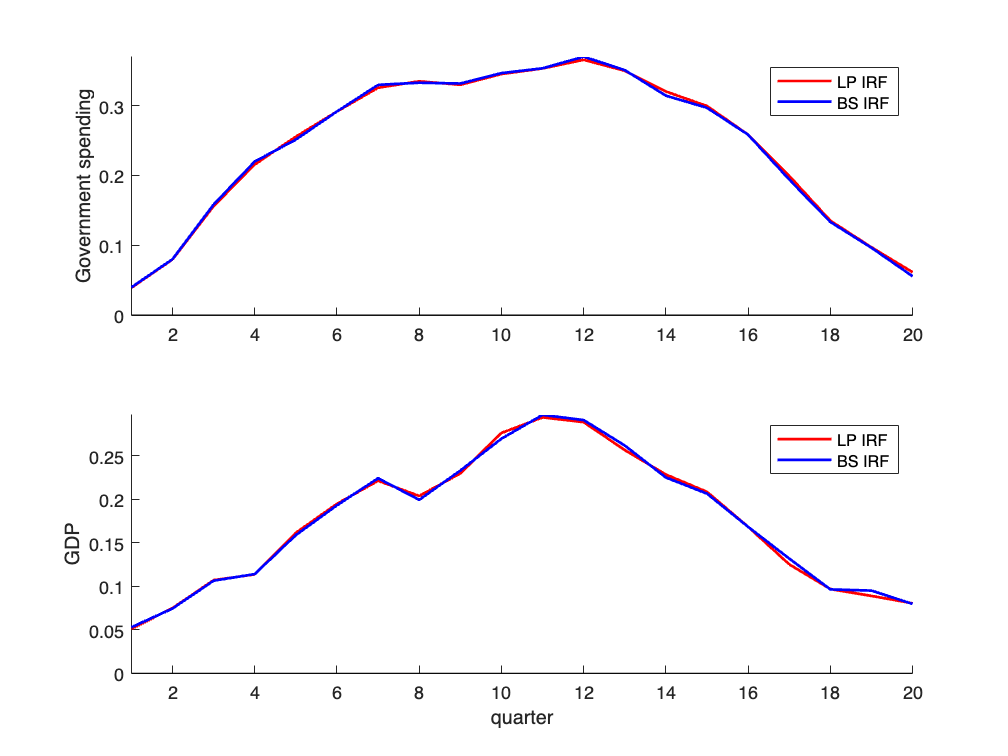

i=1;
figure(3)
subplot(2,1,1)
hold on
% plot point estimates
plot(1:1:hor, liny(i,:), 'Color', 'red','LineWidth', 1.5)
plot(1:1:hor, bs_beta_means(i,:), 'Color', 'blue','LineWidth', 1.5)
plot(1:1:hor, zz, 'k-')
axis tight
ylabel('Government spending')
legend('LP IRF', 'BS IRF')

i=2;
subplot(2,1,2)
hold on
plot(1:1:hor, liny(i,:), 'Color', 'red','LineWidth', 1.5)
plot(1:1:hor, bs_beta_means(i,:), 'Color', 'blue','LineWidth', 1.5)
plot(1:1:hor, zz, 'k-')
axis tight
ylabel('GDP')
xlabel('quarter')
legend('LP IRF', 'BS IRF')